# Analog to Digital Conversion

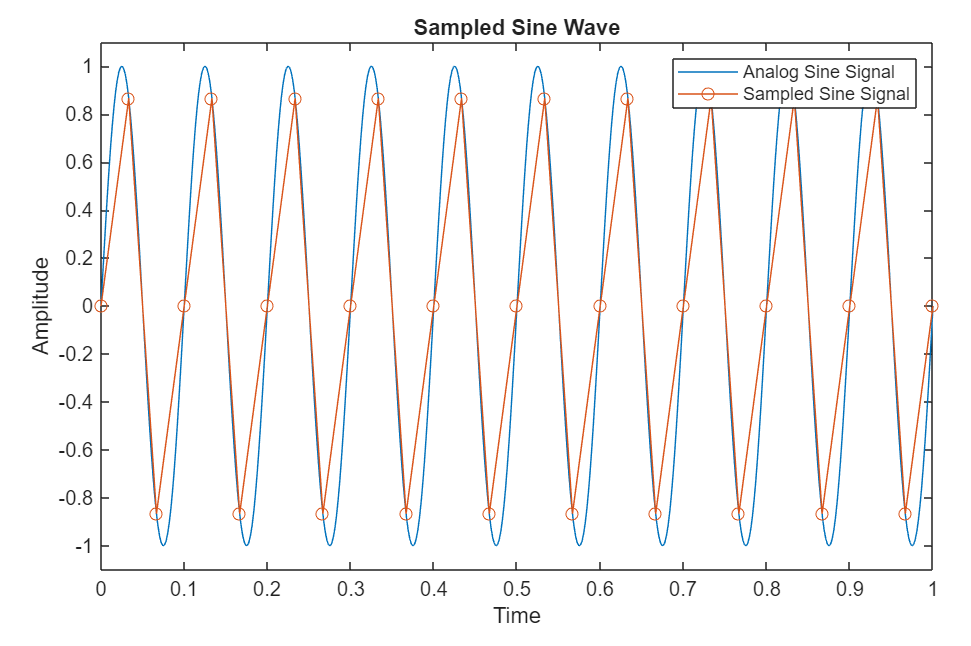

## **Before you get started**

This live script is intended to be used with the code visible and output inline. On the **View** tab of the MATLAB® Toolstrip, in the **View** section, select **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

 Interacting with this live script will build some familiarity with MATLAB as concepts and commands are introduced together. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2-hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if run out of order.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

## Analog signals

Analog signals are continuous signals that vary smoothly over time, representing changes in physical quantities. They can take on any value within a given range, accurately mirroring the subtle nuances of real-world phenomena such as sound, light, or temperature.

### Simple analog signal example

The expression for a simple sine wave can be written as


$$A\;\sin \left(\mathrm{ft}\right)$$


Where $A$ represents the amplitude, $f$ represents the frequency, and $t$ represents the time. This equation can be used to generate sine signals with different properties depending on the values of the variables.

  **Try**. Run the code below to generate a continuous sine wave, which is an analog signal. Experiment with different values of $A$ and $f$ and see how this affects the resulting wave.

% Create a symbolic variable that can be used to generate the analog signal
syms x

% Create the analog sine signal
A = 1;
f = 1;
AnalogSineSig = A * sin(f * x);

% Plot the signal
fplot(AnalogSineSig, [0 2*pi]);
title('Analog Sine Wave');
xlabel('Time');
ylabel('Amplitude');

## Digital signals

Digital signals are discrete representations of information, characterized by binary values, or *bits*, that represent distinct and separate states. This comes in contrast to analog signals, which are continuous.

### Sampling of signals

Sampling is the process of converting a signal into a different signal. It can either entail converting an analog signal into a digital signal, or converting a digital signal into a different digital signal with a different sampling rate. Sampling involves measuring the signal's amplitude at discrete intervals of time in order to construct a new signal.

  **Pro-tip**. A real-world example of the importance of sampling is seen in the use of *accelerometers*, which are sensors used to measure acceleration. Accelerometers sense acceleration as an analog signal, but in order for us to record and use the signal, it needs to be digitized into a series of discrete values. This is where the process of sampling becomes necessary.

#### Sampling the sine wave

To see how sampling works on a real signal, let's sample the sine wave you generated earlier in this script. This will convert it from an analog signal to a digital signal.

  **Try**. Run the code below to sample the analog sine signal. Use the slider to experiment with different sampling rates and observe how that affects the resulting digital signal.

% Define the sampling rate
SamplingRate = 10;

% Generate the sampled sine signal
tSampled = 0:(2*pi/SamplingRate):2*pi;
SampledSineSig = A * sin(f * tSampled);

% Plot the analog and digital signals together
fplot(AnalogSineSig, [0 2*pi]);
hold on;
stairs(tSampled, SampledSineSig, 'o-', SeriesIndex=2);
title('Sampled Sine Wave');
xlabel('Time');
ylabel('Amplitude');
legend(["Analog Sine Signal", "Digital Sine Signal"]);
hold off;

 **Reflect**. What happens as you increase the sampling rate? Can you think of any reasons why in real-world applications, a lower sampling rate might be chosen over a higher one?

### Aliasing

Aliasing is a phenomenon that occurs when a signal is sampled at a sampling frequency that is insufficient to accurately capture the contents of the signal.

  **Try**. To see an example of how aliasing can occur at low sampling frequencies, run the code below. It will plot two different signals that, when sampled at too low of a frequency, can be indistinguishable.

% Generate the two signals and a vector containing their intersecting
% points
t = 0:(1/512):1;
Sig1 = sin(2 * pi * 10 * t);
Sig2 = zeros(1,513);
tIntersect = 0:0.05:1;

% Plot the two signals together
plot(t, Sig1, SeriesIndex=1);
hold on;
plot(t, Sig2, SeriesIndex=2);
scatter(tIntersect, zeros(1,21), 50, 'o', SeriesIndex=4);
title('Aliased Signals');
xlabel('Time');
ylabel('Amplitude');
ylim([-1.1 1.1]);
legend(["Signal 1", "Signal 2"]);
hold off;

 **Reflect**. When sampled at a high enough frequency, we can see that these signals are clearly very different. However, imagine that Signal 1 was the signal you wanted to sample, but you used a sampling frequency of 20Hz such that it was only sampled at the points where it intersects with Signal 2. In this case, your signal would appear as Signal 2, because if it is not sampled at a high enough rate, it will appear as a lower frequency signal (in other words, an *alias*). So how can this be avoided?

### Nyquist Theorem

As you saw in the example above, choosing a sampling rate that is too low can result in massive information loss from the analog signal being sampled. The Nyquist Theorem is a fundamental principle that dictates the minimum sampling rate to accurately reconstruct a signal without loss of information. It states that the sampling rate must be at least twice the highest frequency present in the signal.

 **Exercise 1. **Imagine you are sampling a signal with a maximum frequency of 500 Hz. According to Nyquist Theorem, what is the minimum sampling rate you must use to accurately reconstruct the signal?

            A. 500 Hz

            B. 1000 Hz

            C. 250 Hz

            D. 5000 Hz

A = false; B = false; C = false; D = false;
 

CheckExercise1(A, B, C, D);

## Analog to Digital Conversion (ADC)

Analog to Digital Conversion is the process of converting continuous analog signals into a digital representation. This process involves two key steps: sampling the signal at discrete intervals and then quantizing the sampled values to a set of discrete values.

### Quantization

You have seen how sampling works in the previous example. Now, it's time to learn about the other main step in analog to digital conversion: quantization. Quantization can be defined as approximating each sampled value to a given level of precision; the lower level of precision that is used, the more information that can be lost in the process. Quantization is important because it can have a major effect on the quality of a digital signal.

  **Try**. Use the slider below to change the amount of bits used for quantization and observe the effects on the signal from the previous example.

% Set the number of bits used to represent each sampled value
NumBits = 1;
Quantization = 1 / (2^NumBits - 1);

% Take the sampled sine signal from the previous example with a sampling rate of 200 Hz
t = 0:(1/200):1;
SampledSineSig = sin(2 * pi * 10 * t);

% Quantize the values from the sampled sine signal
QuantizedVals = floor(SampledSineSig / Quantization);
QuantizedSig = QuantizedVals * Quantization;

% Plot the sampled signal and the quantized signal
plot(t, SampledSineSig, SeriesIndex=1);
hold on;
plot(t, QuantizedSig, SeriesIndex=2);
title('Quantized Sine Wave');
xlabel('Time');
ylabel('Amplitude');
ylim([-1.1 1.1]);
legend(["Sampled Sine Signal", "Quantized Sine Signal"]);
hold off;

 **Reflect**. Does the process of quantization introduce any error into the digital signal? Is it possible to quantize a signal without introducing any error?

## Example: Jazz Music

To see these principles of analog to digital conversion in practice, let's apply them to a real-world audio signal: a short recording of a jazz song (credit: Alex-Productions).

  **Try**. Run the code below to load the jazz recording.

[JazzSignal, JazzSamplingFreq] = audioread("Jazz.mp3");
JazzSignal = JazzSignal(200000:600000);
JazzPlayer = audioplayer(JazzSignal, JazzSamplingFreq);

  **Try**. Use the check box below to listen to the jazz recording.

Play = false;
if Play
    play(JazzPlayer);
else
    stop(JazzPlayer);
end

 **Exercise 2. **The human ear can typically hear sounds at frequencies up to a maximum of approximately 20 kHz. Based on your understanding of Nyquist theorem, which of the following would be a reasonable sampling frequency to use for sampling an audio signal?

            A. 10 kHz

            B. 20 kHz

            C. 40 kHz

            D. 80 kHz

A = false; B = false; C = false; D = false;
 

CheckExercise2(A, B, C, D);

Now that you've identified a reasonable sampling rate for an audio signal, let's use the jazz recording as an example of why this is important.

  **Try**. Use the slider below to *downsample* the jazz recording, which will result in a new version of the signal with a lower sampling rate. For example, if you choose a downsampling factor of 2, the recording will be sampled at half of the original sampling rate. Then use the button to listen to the downsampled version of the recording.

% Define the downsampling factor
DownsamplingFactor = 1;

% Downsample the jazz signal using the defined downsampling factor
DownsampledJazzSignal = downsample(JazzSignal, DownsamplingFactor);
DownsampledPlayer = audioplayer(DownsampledJazzSignal, JazzSamplingFreq/DownsamplingFactor);

% Listen to the downsampled version of the jazz recording
Play = false;
if Play
    play(DownsampledPlayer);
else
    stop(DownsampledPlayer);
end

 **Reflect**. Given what you just heard, why is Nyquist Theorem important?

You've seen how the sample rate can affect the quality of an audio signal; now, let's explore the importance of quantization. As context for the activity below, a standard CD uses 16 bits per sample for quantization.

  **Try**. Use the slider below to select a number of bits to represent each sample value.

% Set the number of bits used to represent each sampled value
NumBits = 4;
Quantization = 1 / (2^NumBits - 1);

% Quantize the values from the jazz signal
QuantizedVals = floor(JazzSignal / Quantization);
QuantizedJazzSignal = QuantizedVals * Quantization;
QuantizedPlayer = audioplayer(QuantizedJazzSignal, JazzSamplingFreq);

Play = false;
if Play
    play(QuantizedPlayer);
else
    stop(QuantizedPlayer);
end

## Credits

### Jazz Music

*Creator:* Alex-Productions

*License and link to material: *[https://www.free-stock-music.com/alex-productions-street-food-music-bundle.html](https://www.free-stock-music.com/alex-productions-street-food-music-bundle.html)

## Local Helper Functions

**CheckExercise1**

function CheckExercise1(A, B, C, D)
    if B & ~(A | C | D)
        disp("Correct! Great job");
    elseif A + B + C + D > 1
        disp("Please select just one answer");
    elseif A + B + C + D < 1
        disp("Please select an answer");
    else
        disp("Incorrect." + newline + "According to Nyquist Theorem, what is the relationship between the highest frequency present in a signal" + newline + "and the minimum sampling frequency needed to accurately reconstruct it?");
    end
end

**CheckExercise2**

function CheckExercise2(A, B, C, D)
    if C & ~(A | B | D)
        disp("Correct! Great job." + newline + "Audio signals are typically sampled at 44.1 kHz, which is above the Nyquist frequency you identified.");
    elseif A + B + C + D > 1
        disp("Please select just one answer");
    elseif A + B + C + D < 1
        disp("Please select an answer");
    else
        disp("Incorrect." + newline + "According to Nyquist Theorem, what would be the minimum sampling frequency" + "that would accommodate the full range of frequencies audible by the human ear?");
    end
end